## ELEN 142L Communications and Networking Lab

## Lab 7: Routing

**Dylan Thornburg & Evelyn Arellano Quintero**

The internet is BIG. With billions of connected devices connected, and millions more being connected every day, the scale of the internet is almost too big to imagine. So how does all the data get to the correct devices? With the network changing every second as devices connect and disconnect, how does your data know how to get to you? The answer is routing, which is what we will be looking at today.

Today’s Objective: Get a feel for the complexity of the routing problem by simulating a small network.

## Part 1: Random Routing

Routing is a difficult problem to reason about, so to keep things simple we are going to be considering a small network of just 6 nodes. We will describe today’s network as a directed graph because you will see that not all nodes have a bi-directional connection.

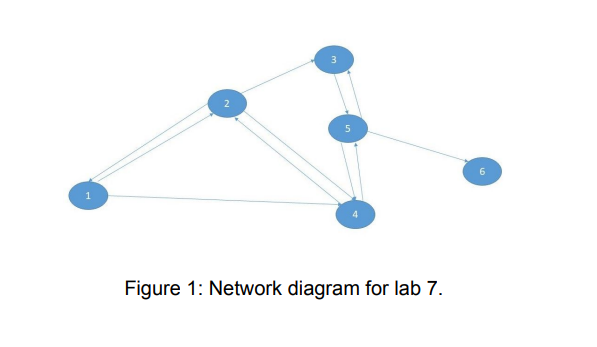

**Step 1:**

Let’s start out by bringing the network from above into MATLAB. We can choose to specify the network in a number of ways, but we will stick to two of the most common - directed graphs and connection matrices.

Will will start with the directed graph. Take a look at the MATLAB page on these structures: Graph with directed edges - MATLAB:

[https://www.mathworks.com/help/matlab/ref/digraph.html](https://www.mathworks.com/help/matlab/ref/digraph.html) 

You can see that one of the most intuitive ways to create a graph is to use a (source, target) mapping. For example, If I wanted to create a connection between nodes one and 2, the source would be 1 and the target would be 2. Create two parallel arrays s and t, and fill them with your mappings, then use the code below to create your graph.

        G = digraph(s,t);

        h = plot(G);

Take a second to make sure that the plot is the same as the one from above - if not, fix your arrays and try again.

Next, we will look at the other method - a connection matrix (also called a routing table). Create a 5x3 array called next_node and fill it with all zeros.

You can think of a connection matrix as just another way to to do the s, t pair from before, where the source is a row, and the targets are the columns. We could specify the connections from node 1 like so:

        next_node(1, :) = [2,4,0];

Notice that we included a third value - zero in this case means not connected. MATLAB won't let us create a matrix that has a variable number of columns, so we add a zero to keep it happy. Fill the rest of next_node with the connections to match the network above. Make sure to enter the connections for each node in increasing order. For example, for node 1, write next_node(1,:) = [2,4,0] rather than next_node(1,:) = [4,2,0]. While this ordering does not affect graph construction in this part, it will be important in the next part, where a weight will be assigned to each edge.

In the next section, we will use the connection matrix - but we don’t want to use those zeros we added for padding. Add this line to your program:

        n_nextnodes = [2, 3, 1, 2, 3, 0];

This variable will tell us how many real connections there are in a row so we don’t get mixed up later.

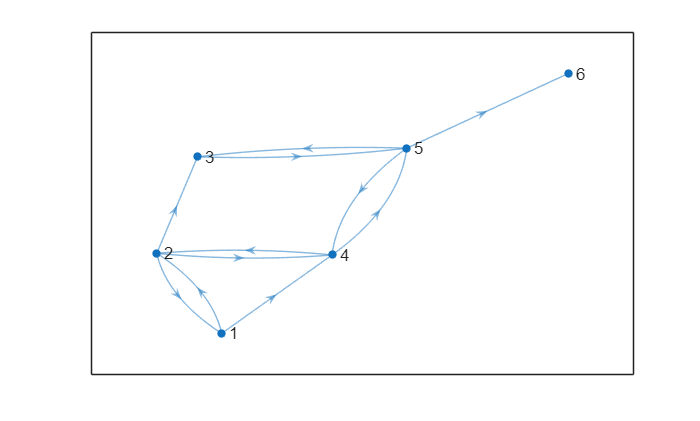

clear;
clc;
close all;

s = [1 1 2 2 2 3 4 4 5 5 5];
t = [2 4 1 3 4 5 2 5 3 4 6];

G = digraph(s,t);
h = plot(G);


next_node = zeros(5,3);
next_node(1,:) = [2,4,0];
next_node(2,:) = [1,3,4];
next_node(3,:) = [5,0,0];
next_node(4,:) = [2,5,0];
next_node(5,:) = [3,4,6];

n_nextnodes = [2, 3, 1, 2, 3, 0];

**Step 2:**

Now let’s try to write an algorithm for finding our way from node 1 to node 6. Our algorithm will be based on chance, so the results may vary quite a bit from run to run - in fact, there is a possibility we will never get there, but the probability of that is very small for our small network.

Let’s start by initializing a few variables:

        saved_routes = [];

        route_lengths = [];

These arrays will hold the results of our routing algorithms - we made them arrays so that we can run the routing multiple times to compare the results. Create a loop that will run 10 times, and inside it place the variables below, then create a while loop that runs until end_node is not zero.

        end_node = 0;

        path = [];

        path(1) = 1;

        n_nodes = 0;

Some explanation of the variables: end_node is a boolean that we will set to 1 when we reach node 6 in our network, path will hold the path we take (starting at node 1), and n_nodes will be an index into our path array.

Now let’s write the routing logic. Your code will need to do as follows:

1. Randomly select one of the connections from the current node.

2. Record the choice made into the path.

3. If we landed at node number 6:

a. Save the route and length into the proper variables, and

b. Break out of the while loop

4. If we aren't at node 6, go to step 1.

Write the code to complete the steps above and verify the results. 

saved_routes = [];
route_lengths = [];

for route_num = 1:10
    end_node = 0;
    path = [];
    path(1) = 1;
    n_nodes = 0;

    while end_node == 0
        cur_node = path(n_nodes + 1);

        rand_index = randi(n_nextnodes(cur_node));
        next = next_node(cur_node, rand_index);

        n_nodes = n_nodes + 1;
        path(n_nodes + 1) = next;

        if next == 6
            end_node = 1;
            saved_routes(route_num,1:length(path)) = path;
            route_lengths(route_num) = n_nodes;
        end
    end
end
saved_routes

saved_routes =      1     2     3     5     4     5     4     2     3     5     3     5     6     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     4     5     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     4     2     3     5     4     5     4     2     3     5     4     5     4     5     4     2     3     5     4     5     3     5     6     0     0
     1     2     1     4     2     4     2     3     5     4     5     4     2     1     4     2     3     5     3     5     3     5     6     0     0     0
     1     2     3     5     3     5     4     5     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     1     4     2     4     5     4     2     1     4     2     4     2     4     2     4     5     4     2     1     4     5     3     5     6
     1     2     3     5     3     5     6 

route_lengths

route_lengths =     12     4    23    22     8    25     6    12    11     3


average_path_length = mean(route_lengths)

average_path_length = 12.6000

What is the average path length?

**It varies, but it's usually in the range of 8-15. In this case, it is 12.6.**

**Step 3:**

Lets see how a path looks when plotted on the network from earlier. Paste in this line:

        highlight(h, path, 'NodeColor','r','EdgeColor','r')

Inspect your plot - how close is it to the shortest route? 

**One plot perfectly follows the shortest route (1->4->5->6 with a distance of 3), but many others are not even close.**

Try a few of the paths you generated and compare them. (Note: you may need to recreate the plot for each path you would like to show.) **Show your result from Part 1 to the TA.**

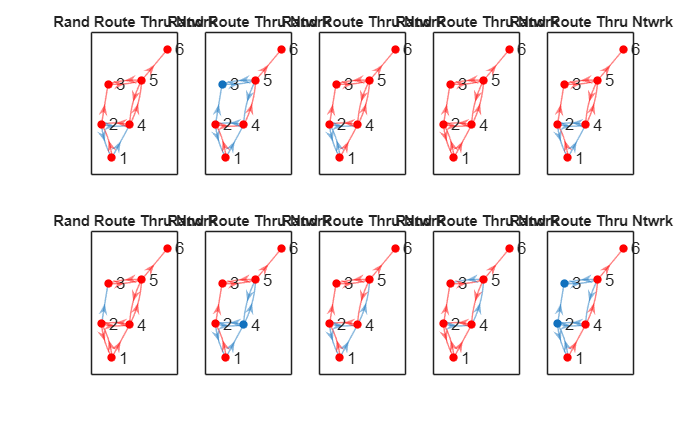

figure;
for i = 1:10
    subplot(2,5,i);
    h = plot(G);
    row = saved_routes(i,:); 
    nodes = row(row ~= 0);       
    highlight(h, nodes, 'NodeColor','r','EdgeColor','r');
    title('Rand Route Thru Ntwrk');
end

## Part 2: Dijkstra’s Algorithm

In the last part, we were able to find a path between nodes 1 and 6, but that path wasn't ideal - in many cases, it likely circled around, going nowhere, until it finally went somewhere else. Think about what that might mean for your internet connection: the experience would be much different!

By this point, you probably have picked out the shortest path (if you haven't, go do so. What we need is a routing algorithm that will find that for us - and lucky for us, a smart Dutch engineer named Edsger Dijkstra created it for us. Dijkstra’s algorithm is one of the most famous there is, and it is used in Google Maps, some telephone networks, and the routing protocols used by the internet.

**Step 1:**

Before we create our own version of Dijkstra’s algorithm, let’s take a second to understand how it works. Dijkstra himself designed it in 20 minutes, and we will see that it is very simple to understand. Here are the steps:

1. Create a list of all of the nodes in the network. At this point, we don’t know the distances between each node (the weights) so mark them all as unvisited, and assign them all a weight of a very large number, like infinity.

2. Pick a node to start at (the current node) - for us, that will be node 1. Mark the current node as visited, and since there is no distance to node 1 since we are currently there, set the distance to zero.

3. For each node that we can get to from the current node, find its distance and update the distance in our node list.

4. If we are at the destination node, or all the nodes we can reach have infinite distance, stop - we are finished. If not, continue on.

5. Pick the node with the smallest distance from the ones we can get to, and visit it. Go to step 3.

That’s all there is to Dijkstra. Take a minute and walk through the network as you would if you were the algorithm - does it match the shortest path from earlier?

**No it does not due to the weights added.**

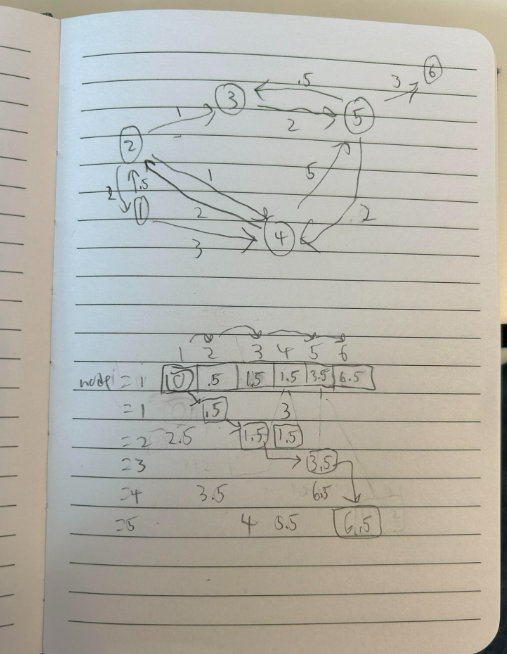

Let’s set up what we need for our Dijkstra implementation. First, we will add weights. Copy in the code below:

        weights = zeros(5,3);

        weights(1, :) = [.5,3,0];

        weights(2, :) = [2,1,1];

        weights(3, :) = [2,0,0];

        weights(4, :) = [2,5,0];

        weights(5, :) = [.5,2,3];

These weights may change which path through the network is the shortest - find the new shortest path. **Verify your answer with the TA.**

Now let's set up the initial conditions.

1. Create a variable distances that is a 1 by 6 vector to hold the distance to each node. Initialize distances to be infinite for all nodes except node 1, which should be zero.

2. Create a variable not_visited, and fill it with all of the nodes not visited yet.

3. Create a variable node_index and initialize it to one.

4. Add this code: cur_node(1) = 1;

weights = zeros(5,3);
weights(1, :) = [.5,3,0];
weights(2, :) = [2,1,1];
weights(3, :) = [2,0,0];
weights(4, :) = [2,5,0];
weights(5, :) = [.5,2,3];

distances = inf(1,6);
distances(1) = 0;
not_visited = 2:6;
node_index = 1;
cur_node(1) = 1;

**Step 2:**

Let’s begin to write our loop. Create a while loop that will loop until the not_visited variable is empty.

Inside the loop, our first goal is to check where we can get to from our current node. Create a variable prev_node which should be a 1x6 vector of all zeros. Next, create a for loop that will loop from 1 to the node_index. Inside the loop, create another 1x6 vector whose components are set to infinity, and name it calculated_distances.

Now we will find the distances to each node - our version of Dijkstra will be slightly different here, because finding and storing the weights is a bit redundant (we have that information in the weights variable already). Instead, we will make a slight variation and find the total path length up to the current point. To do this, paste the long line below into your loop:

calculated_distances(next_node(cur_node(i), 1:n_nextnodes(cur_node(i)))) = ...

     distances(cur_node(i)) + ...

      weights(cur_node(i), 1:n_nextnodes(cur_node(i)));

Don’t be fooled by the length of this line - it's less complicated than it looks. The idea is this: if there is a path to the next node, the total distance is the path from the source to the next node, it just requires a good amount of array indexing to get the data we want.

Now we want to find all the places where the calculated distances were less than the distances we currently have stored. Create a variable updated that has the index of all the smaller distances. Once you have it, we can actually do the update like so:

        distances(updated) = calculated_distances(updated);

And we should also keep track of the node where the new distances originated from:

        prev_node(updated) = cur_node(i);

That finishes the for loop - all that's left is to collect the results and check the exit condition.

% Table = [];
% 
% while ~isempty(not_visited)
%     prev_node = zeros(1,6);
% 
%     for i = 1:node_index
%         calculated_distances = inf(1,6);
% 
%         calculated_distances(next_node(cur_node(i), 1:n_nextnodes(cur_node(i)))) = distances(cur_node(i)) + weights(cur_node(i), 1:n_nextnodes(cur_node(i)));
% 
%         updated = find(calculated_distances <= distances);
% 
%         distances(updated) = calculated_distances(updated);
%         prev_node(updated) = cur_node(i);
%     end
% end

**Step 3:**

Outside of the for loop, the first thing we need to do is to increment the node index. We aos will want a way to look at the results of the algorithm. To do so, use the code below:

        [min_dist, min_index] = min(distances(not_visited));

        cur_node(node_index) = not_visited(min_index);

        Table(node_index-1,:) = [prev_node(not_visited(min_index)), ...

            min_dist, ...

            cur_node(node_index)];

This section of code constructs a matrix called Table. Table will store the paths explored by the algorithm, and the costs between them. If everything works ok, we should see the last entry in Table be the hop from node 5 to node 6, and the distance should match what you calculated as the shortest in the earlier sections.

Finally, we need to update the not_visited array, with this line:

        not_visited = setdiff(not_visited, cur_node(node_index));

And you will need to check the exit condition, i.e. break out of the loop if we reached the destination node.

Run your Dijkstra implementation and inspect the generated Table. 

**Show your results from Part 2 to the TA.**

Table = [];

while ~isempty(not_visited)
    prev_node = zeros(1,6);

    for i = 1:node_index
        calculated_distances = inf(1,6);

        calculated_distances(next_node(cur_node(i), 1:n_nextnodes(cur_node(i)))) = distances(cur_node(i)) + weights(cur_node(i), 1:n_nextnodes(cur_node(i)));

        updated = find(calculated_distances <= distances);

        distances(updated) = calculated_distances(updated);
        prev_node(updated) = cur_node(i);
    end

    node_index = node_index + 1;

    [min_dist, min_index] = min(distances(not_visited));
    cur_node(node_index) = not_visited(min_index);
    Table(node_index-1,:) = [prev_node(not_visited(min_index)), min_dist, cur_node(node_index)];

    not_visited = setdiff(not_visited, cur_node(node_index));

    if cur_node(node_index) == 6
        break;
    end
end

Table

Table =     1.0000    0.5000    2.0000
    2.0000    1.5000    3.0000
    2.0000    1.5000    4.0000
    3.0000    3.5000    5.0000
    5.0000    6.5000    6.0000


distances

distances =          0    0.5000    1.5000    1.5000    3.5000    6.5000


What can you say about what paths were explored? Was the result the shortest path you had chosen? Try changing the weights and seeing how the shortest path changes. 

**The paths that were explored were indeed the same ones that we had chosen. Changing the weights changes the path of course.**

% Second Instance
weights = zeros(5,3);
weights(1, :) = [1,1,0];
weights(2, :) = [1,1,1];
weights(3, :) = [1,0,0];
weights(4, :) = [1,1,0];
weights(5, :) = [1,1,1];

distances = inf(1,6);
distances(1) = 0;
not_visited = 2:6;
node_index = 1;
cur_node(1) = 1;

Table = [];

while ~isempty(not_visited)
    prev_node = zeros(1,6);

    for i = 1:node_index
        calculated_distances = inf(1,6);

        calculated_distances(next_node(cur_node(i), 1:n_nextnodes(cur_node(i)))) = distances(cur_node(i)) + weights(cur_node(i), 1:n_nextnodes(cur_node(i)));

        updated = find(calculated_distances <= distances);

        distances(updated) = calculated_distances(updated);
        prev_node(updated) = cur_node(i);
    end

    node_index = node_index + 1;

    [min_dist, min_index] = min(distances(not_visited));
    cur_node(node_index) = not_visited(min_index);
    Table(node_index-1,:) = [prev_node(not_visited(min_index)), min_dist, cur_node(node_index)];

    not_visited = setdiff(not_visited, cur_node(node_index));

    if cur_node(node_index) == 6
        break;
    end
end

Table

Table =      1     1     2
     1     1     4
     2     2     3
     4     2     5
     5     3     6


distances

distances =      0     1     2     1     2     3


**When we set all of the weights to 1 (or 0 for no path), we can see that our ideal path and distance matches the shortest hops path from part 1.**

## Report

Submit your codes and answers to questions on camino. In addition, discuss the following questions with your partner and attach your answers to the end of your report.

1. What did you observe from the experiments?

**We observed how networking devices/routers actually communicate with each other by modeling them as a graph. We also observed how Dijkstra’s algorithm helps networking devices choose the quickest path to relay information.**

2. If you could expand this experiment how would you do it?

**More nodes and add data into it. **

3. How does the experiment relate to the course topic?

**This experiment simulated networks which is perfectly relevant to the material on networks and communications.**

4. What did you learn from the experiment?

**We learned how internet traffic is actually routed through our graph model.**